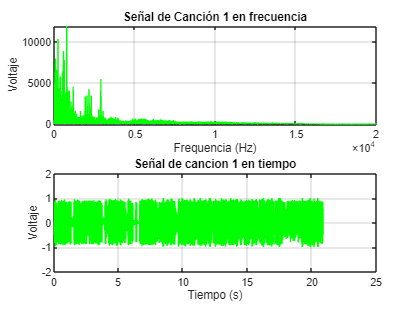

%PROYECTO FINAL
%OTOÑO 2021
%Equipo 4 
%Jocelyne Gonzalez Hernandez (225369-5)
%Jazmin Villegaz Hernandez (216247-A)

%1) Definir señal de mensaje para cancion 1 2 y 3
% definición de la señal de audio por ruta relativa: cancion 1
[audio, fs] = audioread('cancion1.wav');

% definición de la señal de audio por ruta relativa: cancion 2
[audio2, fs2] = audioread('cancion2.wav');

% definición de la señal de audio por ruta relativa: cancion 3
[audio3, fs3] = audioread('cancion3.wav');

% transformada de fourier sobre la señal de audio 1
fft_signal = fft(audio); 

% transformada de fourier sobre la señal de audio 2
fft_signal2 = fft(audio2); 

% transformada de fourier sobre la señal de audio 3
fft_signal3 = fft(audio3); 

%definicion en tiempo de la duracion de las 3 canciones: 
duracion1 = (length(audio)-1) / fs; 
periodo1 = 0:1/fs:duracion1;
%-----------------------------------
duracion2 = (length(audio2)-1) / fs2; 
periodo2 = 0:1/fs2:duracion2;
%-----------------------------------
duracion3 = (length(audio3)-1) / fs3; 
periodo3 = 0:1/fs3:duracion3;

% grafica de la señal original 1 en dominio frequencial y temporal
figure(1)
subplot(2,1,1)
dom_frequencialA = (0:length(audio)-1)*(fs/length(audio));
plot(dom_frequencialA, abs(fft_signal), 'g')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Señal de Canción 1 en frecuencia')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,2)
plot(periodo1, audio,'g')
grid on
xlabel('Tiempo (s)')
ylabel('Voltaje')
ylim([-2 2])
title('Señal de cancion 1 en tiempo')

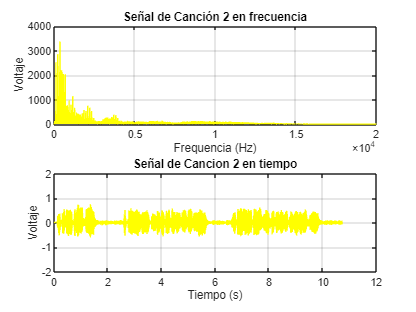


% grafica de la señal original 2 en dominio frequencial 
figure(2)
subplot(2,1,1)
dom_frequencialB = ((0:length(audio2)-1)*(fs/length(audio2)));
plot(dom_frequencialB, abs(fft_signal2), 'y')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Señal de Canción 2 en frecuencia')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,2)
plot(periodo2, audio2, 'y')
grid on
xlabel('Tiempo (s)')
ylabel('Voltaje')
ylim([-2 2])
title('Señal de Cancion 2 en tiempo')

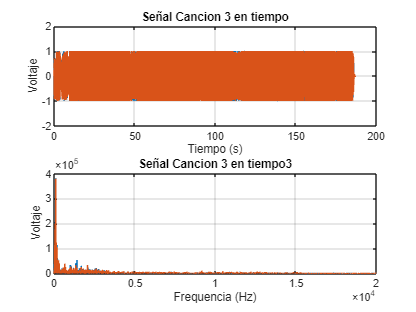

% grafica de la señal original 3 en dominio frequencial 
figure(3)
subplot(2,1,2)
dom_frequencialC = (0:length(audio3)-1)*(fs/length(audio3));
plot(dom_frequencialC, abs(fft_signal3))
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Señal Cancion 3 en tiempo3')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,1)
plot(periodo3, audio3)
grid on
xlabel('Tiempo (s)')
ylabel('Voltaje')
ylim([-2 2])
title('Señal Cancion 3 en tiempo')


%2) Definir señales portadoras
% definición de señal poradora ... freq = 530khz
portadora_freq1 = 580000; % frequencia de portadora en Hz
t_portadora = 0:1/fs:duracion1; % Dominio en el tiempo
portadora = cos(2*pi*portadora_freq1*t_portadora);

% definición de señal poradora ... freq = 530khz
portadora_freq2 = 800000; % frequencia de portadora en Hz
t2_portadora = 0:1/fs:duracion2; % Dominio en el tiempo
portadora2 = cos(2*pi*portadora_freq2*t2_portadora);

% definición de señal poradora ... freq = 530khz
portadora_freq3 = 950000; % frequencia de portadora en Hz
t3_portadora = 0:1/fs:duracion3; % Dominio en el tiempo
portadora3 = cos(2*pi*portadora_freq3*t3_portadora);

%3)Proceso de modulación 

modulada = audio .* portadora';
modulada2 = audio2 .* portadora2';
modulada3 = audio3 .* portadora3';

disp(length(modulada));

     1001712



disp(length(modulada2));

      514944



disp(length(modulada3));

     8990208



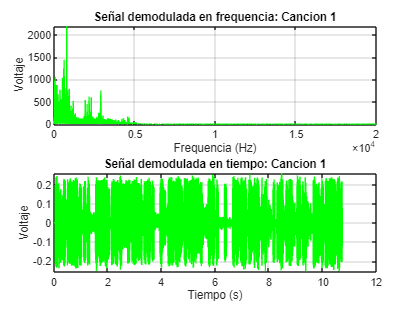


min_length = min([length(modulada), length(modulada2), length(modulada3)]);

a = modulada(1:min_length, 1);
b = modulada2(1:min_length, 1);
c = modulada3(1:min_length, 1);

modulated_complete = a + b + c; 

% Normalize the modulated signal
modulated_complete = modulated_complete / max(abs(modulated_complete));


%4) Proceso de demodulación
duracion = (length(modulated_complete)-1) / fs; 

% definición de señal poradora ... freq = 530khz
portadora_freq1 = 580000; % frequencia de portadora en Hz
t = 0:1/fs:duracion; % Dominio en el tiempo
portadora = cos(2*pi*portadora_freq1*t);

% definición de señal poradora ... freq = 530khz
portadora_freq2 = 800000; % frequencia de portadora en Hz
t2 = 0:1/fs:duracion; % Dominio en el tiempo
portadora2 = cos(2*pi*portadora_freq2*t2);

% definición de señal poradora ... freq = 530khz
portadora_freq3 = 950000; % frequencia de portadora en Hz
t3 = 0:1/fs:duracion; % Dominio en el tiempo
portadora3 = cos(2*pi*portadora_freq3*t3);

% demodulación
demodulada1 = modulated_complete .* portadora';
demodulada2 = modulated_complete .* portadora2';
demodulada3 = modulated_complete .* portadora3';

%5) Filtrado
% s1 --------------------------------------------------
% low pass filter
cutoff_freq =  2500; % Cutoff frequency in Hz (set to the highest audible frequency, 20 kHz)
demodulada_filtered1 = lowpass(demodulada1, cutoff_freq, fs);

% s2 --------------------------------------------------
% low pass filter
cutoff_freq =  4600; % Cutoff frequency in Hz (set to the highest audible frequency, 20 kHz)
demodulada_filtered2 = lowpass(demodulada2, cutoff_freq, fs);

% s3 --------------------------------------------------
% low pass filter
cutoff_freq =  3500; % Cutoff frequency in Hz (set to the highest audible frequency, 20 kHz)
demodulada_filtered3 = lowpass(demodulada3, cutoff_freq, fs3);

% guardar señal modulada en nueva variable
audiowrite('demod_s1.wav', demodulada_filtered1, fs);
% guardar señal modulada en nueva variable
audiowrite('demod_s2.wav', demodulada_filtered2, fs2);
% guardar señal modulada en nueva variable
audiowrite('demod_s3.wav', demodulada_filtered3, fs3);

%6) graficas de las señales demoduladas en dominio frequencial y temporal

% señal demodulada 1 en freq y temporal
[demod_s1, fs1] = audioread('demod_s1.wav'); 
fft_demod1 = fft(demod_s1); 
dom_frequencial = (0:length(demod_s1)-1)*(fs1/length(demod_s1));

figure(5)
subplot(2,1,1)
plot(dom_frequencial, abs(fft_demod1), 'g')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Señal demodulada en frequencia: Cancion 1')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,2)
t_demod1 = (0:length(demod_s1)-1) / fs1;  % Dominio en el tiempo
plot(t_demod1, demod_s1, 'g')
xlabel('Tiempo (s)')
ylabel('Voltaje')
title('Señal demodulada en tiempo: Cancion 1')
grid on

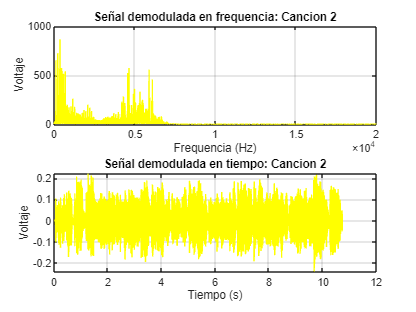


% señal demodulada 2 en freq y temporal
[demod_s2, fs2] = audioread('demod_s2.wav'); 
fft_demod2 = fft(demod_s2); 
dom_frequencial2 = (0:length(demod_s2)-1)*(fs2/length(demod_s2));

figure(6)
subplot(2,1,1)
plot(dom_frequencial2, abs(fft_demod2), 'y')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Señal demodulada en frequencia: Cancion 2')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,2)
t_demod2 = (0:length(demod_s2)-1) / fs2;  % Dominio en el tiempo
plot(t_demod2, demod_s2, 'y')
xlabel('Tiempo (s)')
ylabel('Voltaje')
title('Señal demodulada en tiempo: Cancion 2')
grid on

b = audio2(1:length(demod_s2), 1);
corrcoef(b, demod_s2)

ans =     1.0000    0.7082
    0.7082    1.0000


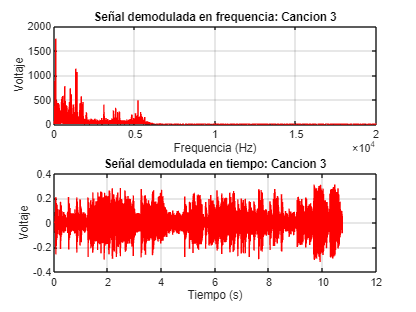



% señal demodulada 3 en freq y temporal
[demod_s3, fs] = audioread('demod_s3.wav'); 
fft_demod3 = fft(demod_s3); 
dom_frequencial3 = (0:length(demod_s3)-1)*(fs/length(demod_s3));

figure(7)
subplot(2,1,1)
plot(dom_frequencial3, abs(fft_demod3), 'r')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Señal demodulada en frequencia: Cancion 3')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,2)
t_demod3 = (0:length(demod_s3)-1) / fs3;  % Dominio en el tiempo
plot(t_demod3, demod_s3, 'r')
xlabel('Tiempo (s)')
ylabel('Voltaje')
title('Señal demodulada en tiempo: Cancion 3')
grid on

c = audio3(1:length(demod_s3), 1);
corrcoef(c, demod_s3);